## **Introduction**

Lens antennas offer a low cost solution to beam forming. They can be used to shape radiation pattern from a closely located source through the controlled distribution of the dielectric and magnetic material properties throughout the lens. Recent advances in manufacturing techniques, such as multi-material 3D printing, has allowed us to realise these devices where the material properties change throughout the lens. Further, new materials with unique properties are available to use within the device. 3D printing also offers a simple way of controlling the effective dielectric properties at microwave and milimetre wave frequencies, by controlling the infill ratio of filament/resin/material to air. 

All these degrees of freedom allow us a large design space with many degrees of freedom (material prorperties, lens geometry and dimensions, frequency of operation etc) which may allow us to design and realise lenses with advanced beamforming prorperties. For example, rather than just designing a lens that produces a directive beam at boresight, we may want a broad beam providing perfect coverage to sector of 3D space. We may want multiple beams with different beamwidths in different directions. Or we may want a single lens providing focussing to different focal spots at different frequencies for a shared-aperture solution.

Machine learning can help us to optimize the lens parameters in order to realise these types of designs. By learning from the data produced through from a number of EM simulations, the ML model should then be able to predict the radiation pattern response based upon the parameters of the lens. 

This tutorial uses the lens_optimizer program, which optimizes the properties of a purely dielectric lens through a regression ensemble model using supervised machine learning for customisable, multi-beam radiation patterns. The lens is divided into nX by nY pixels, each with its own dielectric properties that are confined between a user-specified range. The width, thickness, frequency and focal distance can all be defined by the user.

### Create The lens_optimizer object with the default parameters

Default parameters are as follows:

lens_width = 250 mm, t = 50 mm, nX = 20, nY = 4, min_permittivity = 1; max_permittivity = 5; frequency = 10 GHz, focal_distance = 25 mm

lens_obj = lens_optimizer;

The class constructor returns an object that contains a random permittivity map representing the dielectric lens. We can view the lens:

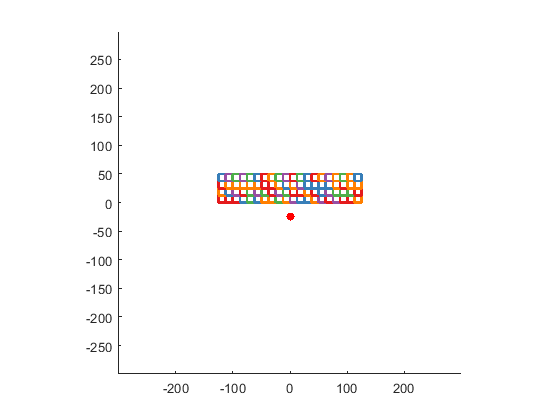

lens_obj.plotSetup;

The different colours represent different values of permittivity for each pixel in the lens. 

We can simulate the response of this lens from a line source positioned at the focal distance in the centre of the x-axis behind the lens. The simulator used here is the maxwellFDFD package from Wonseok Shin / MIT (https://github.com/wsshin/maxwellfdfd). Simulations are in 1D, as the total solver time is about 10 seconds in this example. Generally, the simulation package could easily be replaced by a commercial full wave solver, as long as the inputs (the lens material matrix) and outputs (the electric field map or far field response) remain the same.

The simulate method on its own returns the E field, H field, object array and source array containing information about the simulation. The far field can be approximated from this data using the near2FarApprox function written specifically for this simulation package.

maxwell_run begins.
E-field grid type: primary
time elapsed: 0.058851 sec in total, 0.058851 sec for initial setup
	Length Unit: 1.000000e-09 m
	wvlen = 29.9792, freq = 41.3567 eV
materials used:
	M1 (lossless): eps = [1 1.5 1.5;1.5 1 1.5;1.5 1.5 1], mu = 1
	M2 (lossless): eps = 1.5, mu = 1
	M3 (lossless): eps = [2 1.5 1.5;1.5 2 1.5;1.5 1.5 2], mu = 1
	M4 (lossless): eps = [2.5 1.5 1.5;1.5 2.5 1.5;1.5 1.5 2.5], mu = 1
	M5 (lossless): eps = [3 1.5 1.5;1.5 3 1.5;1.5 1.5 3], mu = 1
	vacuum: eps = [1 0 0;0 1 0;0 0 1], mu = [1 0 0;0 1 0;0 0 1]


time elapsed: 0.10087 sec in total, 0.042019 sec for uniform grid generation
	[Nx Ny Nz] = [600 600 1]
time elapsed: 0.93621 sec in total, 0.83534 sec for eps and mu assignment


time elapsed: 1.0748 sec in total, 0.13854 sec for J assignment
time elapsed: 11.6361 sec in total, 10.5613 sec for solution calculation
solve for: E-field
maxwell_run finishes.



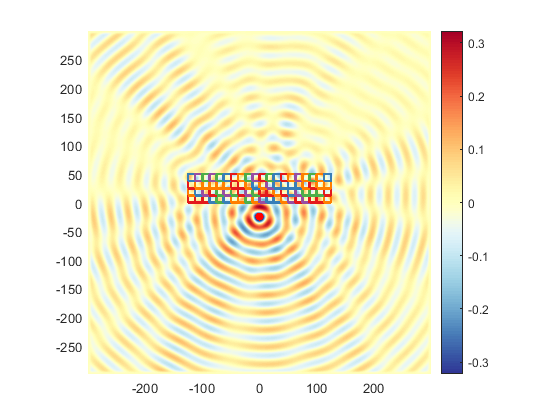

[E, H, obj_array, src_array] = lens_obj.simulate; %Simulate the response of the random permittivity map. 

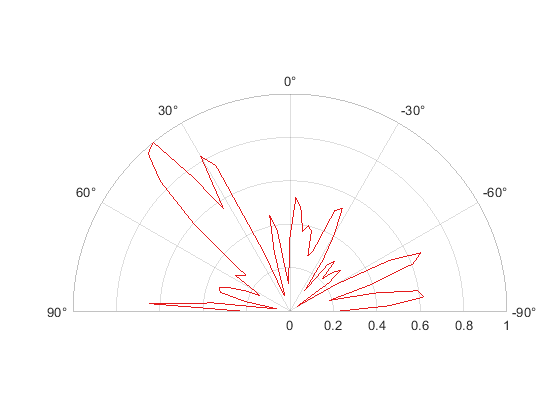

%% Retrieve the normalized far field
[E_far,phi] = near2FarApprox(E,obj_array,src_array);

%Plot the far field 
pAx = polaraxes('parent',figure);
polarplot(pAx,phi,E_far);
pAx.ThetaLim = [-90 90];
pAx.ThetaZeroLocation = 'top';

In this example, our lens has 5 x 20 pixels, each with a possibility of one of 5 discrete permittivity values. Each pixel is a parameter in the design space, so we have 100 parameters with a total of 100^5 = 1e10 possible combinations. In order to utilize the power of ML, we need data. And we need data that is representative of the types of beams we want to produce. The lens_optimizer object contains a generate_optimized_training_data method that generates training data through 4 different optimisation problems. The optimisation problems attempt to design a lens with a specific beam pattern. Each time a simulation is run, the permittivity map and far field response are saved in a directory on the hard drive. I am currently using the surrogate_opt package in matlab as this includes a number of random samples in the optimisation process, but any optimizer could be used. This also speeds up the optimisation process for costly functions such as ours. 

generate_training_dataset = 0;
if generate_training_dataset  % Running this takes a while!
    lens_obj.generate_optimized_training_data;
end

%% Read the data from disk
lens_obj.read_data_from_disk;


The dataset is pretty large. There are 5769 simulations. In each simulation, we have a 91 x 80 input matrix, containing the 80 permittivity values and the phi value for prediction. We can probably reduce the size of the dataset quite substantially without losing performance, by randomly removing entries so we dont have to train on every phi value for every permittivity map.

factor = 0.5;
lens_obj.reduce_dataset(factor);

Now we have data, we can use this to train ML models which are able to predict the far field response based on the permittivity map. Because we have tabular data, we can use a classical machine learning model for regression. There appears to be a number to choose from such as XG-Boost, Random Forest, GradientBoosting... frsnca performs feature selection using neighborhood component analysis for regression directly in matlab. Here is how we implement it. This code can be called directly in the lens_opt object by calling the create_model method, which then stores the model as a parameter in the model.

%  create a model using feature selection for regression with nearest component analysis 

%partition the data set for training and test
hpartition = cvpartition(length(lens_obj.outputdata),'Holdout',0.3);
idxTrain = training(hpartition);
idxTest = test(hpartition);

Xtrain = lens_obj.inputdata(idxTrain,:);
Ytrain = lens_obj.outputdata(idxTrain,:);

Xtest = lens_obj.inputdata(idxTest,:);
Ytest = lens_obj.outputdata(idxTest,:);

%train the model
ts = tic;
mdl = fsrnca(Xtrain,Ytrain,'Standardize',true);
toc(ts)

Elapsed time is 328.859725 seconds.


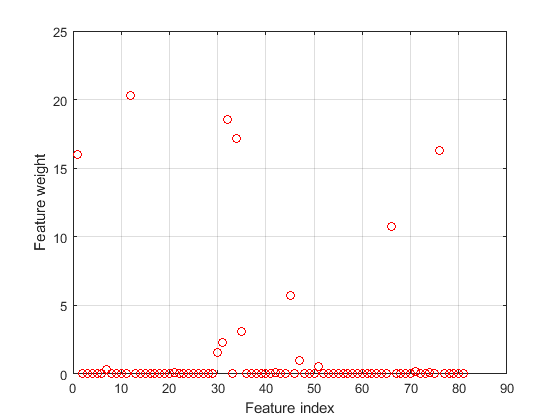


%plot the feature weights and the loss
hAx = axes('parent',figure);
plot(hAx,mdl.FeatureWeights,'ro')
xlabel('Feature index')
ylabel('Feature weight')
grid on

ts = tic;
L = loss(mdl,Xtest,Ytest)

L =       0.04687

toc(ts)

Elapsed time is 99.188163 seconds.



%Plot the computed and actual responses for the test values
ts = tic;
Ypred = predict(mdl,Xtest);
toc(ts)

Elapsed time is 100.418952 seconds.


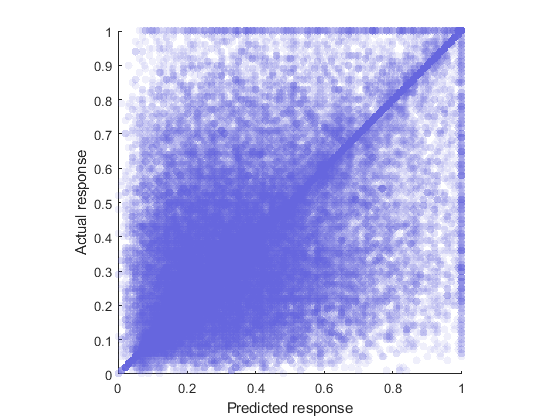


hAx = axes('parent',figure);
s = scatter(hAx,Ypred,Ytest,'o','markerfacecolor',[0.4 0.4 0.87],'markerfacealpha',0.1,'MarkerEdgeColor','none');
xlabel('Predicted response')
ylabel('Actual response')
axis equal
xlim([0 1])
ylim([0 1])

We can see non-zero feature weights, and some features clearly have more weight than others. The performance of fsrnca can be improved by tuning the regularization parameter, lambda. This can be done with five-fold cross validation. Tuning lamda means finding the lamda value that produces the minimum regression loss.



% Partition the data into five folds. For each fold, cvpartition assigns 4/5th of the data as a training set, and 1/5th of the data as a test set.
n = length(Ytrain);
cvp = cvpartition(length(Ytrain),'kfold',5);
numvalidsets = cvp.NumTestSets;

% Assign the λ values for the search
lambdavals = linspace(0,50,20)*std(Ytrain)/n;

%create an array to store the loss values
lossvals = zeros(length(lambdavals),numvalidsets);

for i = 1:length(lambdavals)
    fprintf('Model Optimisation Started\nOptimising model@:Training model with lamda value %i out of %d',i,lambdavals);
        ts = tic;
    for k = 1:numvalidsets
        X = Xtrain(cvp.training(k),:);
        y = Ytrain(cvp.training(k),:);
        Xvalid = Xtrain(cvp.test(k),:);
        yvalid = Ytrain(cvp.test(k),:);

        
        nca = fsrnca(X,y,'FitMethod','exact', ...
            'Solver','minibatch-lbfgs','Lambda',lambdavals(i), ...
            'GradientTolerance',1e-4,'IterationLimit',30,'Standardize',true);
        

        lossvals(i,k) = loss(nca,Xvalid,yvalid,'LossFunction','epsiloninsensitive');
    end
    toc(ts)
end

Training model set 1 out of 5

Elapsed time is 15.077992 seconds.


Training model set 2 out of 5

Elapsed time is 14.544614 seconds.


Training model set 3 out of 5

Elapsed time is 14.360082 seconds.


Training model set 4 out of 5

Elapsed time is 15.080806 seconds.


Training model set 5 out of 5

Elapsed time is 14.824402 seconds.


Training model set 1 out of 5

Elapsed time is 15.192821 seconds.


Training model set 2 out of 5

Elapsed time is 14.321279 seconds.


Training model set 3 out of 5

Elapsed time is 14.630238 seconds.


Training model set 4 out of 5

Elapsed time is 14.293525 seconds.


Training model set 5 out of 5

Elapsed time is 15.733035 seconds.


Training model set 1 out of 5

Elapsed time is 14.956866 seconds.


Training model set 2 out of 5

Elapsed time is 15.259222 seconds.


Training model set 3 out of 5

Elapsed time is 14.524760 seconds.


Training model set 4 out of 5

Elapsed time is 15.208635 seconds.


Training model set 5 out of 5

Elapsed time is 15.018804 seconds.


Training model set 1 out of 5

Elapsed time is 14.566930 seconds.


Training model set 2 out of 5

Elapsed time is 14.183550 seconds.


Training model set 3 out of 5

Elapsed time is 14.240042 seconds.


Training model set 4 out of 5

Elapsed time is 14.312424 seconds.


Training model set 5 out of 5

Elapsed time is 16.227977 seconds.


Training model set 1 out of 5

Elapsed time is 14.515306 seconds.


Training model set 2 out of 5

Elapsed time is 15.108080 seconds.


Training model set 3 out of 5

Elapsed time is 14.492649 seconds.


Training model set 4 out of 5

Elapsed time is 14.285213 seconds.


Training model set 5 out of 5

Elapsed time is 14.196903 seconds.


Training model set 1 out of 5

Elapsed time is 14.903084 seconds.


Training model set 2 out of 5

Elapsed time is 14.258844 seconds.


Training model set 3 out of 5

Elapsed time is 14.934422 seconds.


Training model set 4 out of 5

Elapsed time is 13.848976 seconds.


Training model set 5 out of 5

Elapsed time is 14.494137 seconds.


Training model set 1 out of 5

Elapsed time is 14.619284 seconds.


Training model set 2 out of 5

Elapsed time is 14.821532 seconds.


Training model set 3 out of 5

Elapsed time is 14.807195 seconds.


Training model set 4 out of 5

Elapsed time is 15.399093 seconds.


Training model set 5 out of 5

Elapsed time is 14.477083 seconds.


Training model set 1 out of 5

Elapsed time is 14.657546 seconds.


Training model set 2 out of 5

Elapsed time is 15.059379 seconds.


Training model set 3 out of 5

Elapsed time is 14.250568 seconds.


Training model set 4 out of 5

Elapsed time is 14.949303 seconds.


Training model set 5 out of 5

Elapsed time is 15.005501 seconds.


Training model set 1 out of 5

Elapsed time is 14.764071 seconds.


Training model set 2 out of 5

Elapsed time is 15.392072 seconds.


Training model set 3 out of 5

Elapsed time is 16.170553 seconds.


Training model set 4 out of 5

Elapsed time is 14.300968 seconds.


Training model set 5 out of 5

Elapsed time is 16.193739 seconds.


Training model set 1 out of 5

Elapsed time is 14.778011 seconds.


Training model set 2 out of 5

Elapsed time is 14.936069 seconds.


Training model set 3 out of 5

Elapsed time is 14.514042 seconds.


Training model set 4 out of 5

Elapsed time is 14.674540 seconds.


Training model set 5 out of 5

Elapsed time is 14.600478 seconds.


Training model set 1 out of 5

Elapsed time is 23.376177 seconds.


Training model set 2 out of 5

Elapsed time is 17.810243 seconds.


Training model set 3 out of 5

Elapsed time is 14.070265 seconds.


Training model set 4 out of 5

Elapsed time is 14.813485 seconds.


Training model set 5 out of 5

Elapsed time is 14.728300 seconds.


Training model set 1 out of 5

Elapsed time is 16.909042 seconds.


Training model set 2 out of 5

Elapsed time is 19.422550 seconds.


Training model set 3 out of 5

Elapsed time is 18.645311 seconds.


Training model set 4 out of 5

Elapsed time is 15.473021 seconds.


Training model set 5 out of 5

Elapsed time is 14.900897 seconds.


Training model set 1 out of 5

Elapsed time is 16.394952 seconds.


Training model set 2 out of 5

Elapsed time is 14.682148 seconds.


Training model set 3 out of 5

Elapsed time is 14.908954 seconds.


Training model set 4 out of 5

Elapsed time is 14.651928 seconds.


Training model set 5 out of 5

Elapsed time is 14.908159 seconds.


Training model set 1 out of 5

Elapsed time is 15.318028 seconds.


Training model set 2 out of 5

Elapsed time is 14.691215 seconds.


Training model set 3 out of 5

Elapsed time is 15.194252 seconds.


Training model set 4 out of 5

Elapsed time is 16.373820 seconds.


Training model set 5 out of 5

Elapsed time is 14.954899 seconds.


Training model set 1 out of 5

Elapsed time is 14.250765 seconds.


Training model set 2 out of 5

Elapsed time is 14.369668 seconds.


Training model set 3 out of 5

Elapsed time is 14.751272 seconds.


Training model set 4 out of 5

Elapsed time is 13.872469 seconds.


Training model set 5 out of 5

Elapsed time is 13.835185 seconds.


Training model set 1 out of 5

Elapsed time is 14.268090 seconds.


Training model set 2 out of 5

Elapsed time is 14.633415 seconds.


Training model set 3 out of 5

Elapsed time is 14.469251 seconds.


Training model set 4 out of 5

Elapsed time is 13.491528 seconds.


Training model set 5 out of 5

Elapsed time is 14.232038 seconds.


Training model set 1 out of 5

Elapsed time is 13.735369 seconds.


Training model set 2 out of 5

Elapsed time is 14.475017 seconds.


Training model set 3 out of 5

Elapsed time is 14.530328 seconds.


Training model set 4 out of 5

Elapsed time is 14.230407 seconds.


Training model set 5 out of 5

Elapsed time is 14.545099 seconds.


Training model set 1 out of 5

Elapsed time is 14.639780 seconds.


Training model set 2 out of 5

Elapsed time is 14.499993 seconds.


Training model set 3 out of 5

Elapsed time is 14.958435 seconds.


Training model set 4 out of 5

Elapsed time is 13.471040 seconds.


Training model set 5 out of 5

Elapsed time is 14.070715 seconds.


Training model set 1 out of 5

Elapsed time is 14.798963 seconds.


Training model set 2 out of 5

Elapsed time is 14.502990 seconds.


Training model set 3 out of 5

Elapsed time is 14.035882 seconds.


Training model set 4 out of 5

Elapsed time is 14.003558 seconds.


Training model set 5 out of 5

Elapsed time is 14.355126 seconds.


Training model set 1 out of 5

Elapsed time is 14.994474 seconds.


Training model set 2 out of 5

Elapsed time is 14.411754 seconds.


Training model set 3 out of 5

Elapsed time is 14.592336 seconds.


Training model set 4 out of 5

Elapsed time is 15.807107 seconds.


Training model set 5 out of 5

Elapsed time is 16.869201 seconds.


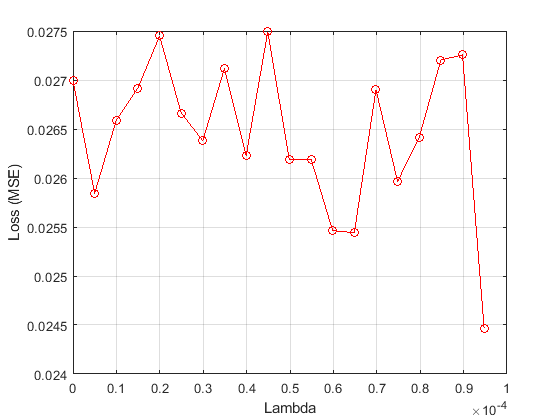

%plot the


% Compute the average loss obtained from the folds for each λ value and plot versus its lamda value
meanloss = mean(lossvals,2);
figure
plot(lambdavals,meanloss,'ro-')
xlabel('Lambda')
ylabel('Loss (MSE)')
grid on


% find the lambda value with the minimum loss
[~,idx] = min(meanloss);

idx =      7

bestlambda = lambdavals(idx)

bestlambda =     3.717e-05

bestloss = meanloss(idx)

bestloss =      0.028407


%retrain the model with the best lambda value
nca = fsrnca(Xtrain,Ytrain,'FitMethod','exact', ...
    'Solver','lbfgs','Lambda',bestlambda);
%plot selected feature weights, the 

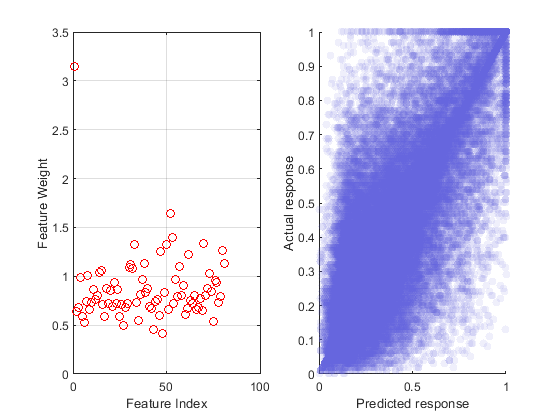


hFig = figure;
hAx1 = subplot(1,2,1,'parent',hFig('position',[680 671 768 307]));
plot(hAx1,nca.FeatureWeights,'ro');
xlabel('Feature Index')
ylabel('Feature Weight')
grid on
hAx1.YLim(1) = 0;
hAx2 = subplot(1,2,2,'parent',hFig);
Ypred = predict(nca,Xtest);
s = scatter(hAx2,Ypred,Ytest,'o','markerfacecolor',[0.4 0.4 0.87],'markerfacealpha',0.1,'MarkerEdgeColor','none');
xlabel('Predicted response')
ylabel('Actual response')

No we can visualise the performance of our model with respect to our original data

%test performance of model

%set the lens_optimizer objer  model property to equal the trained model. Then call the predict_model method which will
%predict the far field for a given permittivity map for all values of phi between -90:90
lens_obj.mdl = nca;

%select a random permittivity map from the imput data
idx = randi(size(lens_obj.inputdata,1)); 
map = lens_obj.inputdata(idx,2:end); 

%predict its farfield using model
ts = tic;
Efar = lens_obj.predict_model(map);
toc(ts);

Elapsed time is 0.752032 seconds.


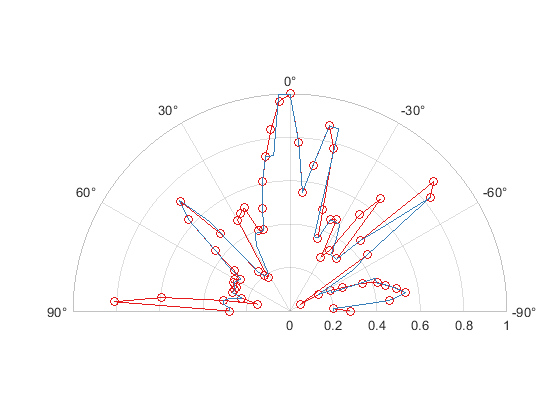

%calculate the far field
[E, ~, obj_array, src_array]= lens_obj.simulate(map,'plot',false); 
[E_far_sim,phi] = near2FarApprox(E,obj_array,src_array);

pAx = polaraxes('parent',figure); 
polarplot(phi,E_far_sim,'-o'); 
hold on; 
polarplot(phi,Efar);
pAx.ThetaLim = [-90 90];
pAx.ThetaZeroLocation = 'top';

%predict a new far field response using random data...
map = randi(5,80,1)';
ts = tic;
Efar = lens_obj.predict_model(map);
toc(ts);

Elapsed time is 1.465432 seconds.


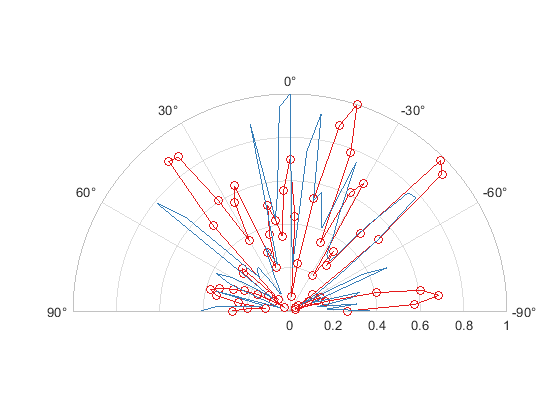

%calculate the far field
[E, ~, obj_array, src_array]= lens_obj.simulate(map,'plot',false); 
[E_far_sim,phi] = near2FarApprox(E,obj_array,src_array);

pAx = polaraxes('parent',figure); 
polarplot(phi,E_far_sim,'-o'); 
hold on; 
polarplot(phi,Efar);
pAx.ThetaLim = [-90 90];
pAx.ThetaZeroLocation = 'top';

Now we have a model that can predict the far field response of the lens accurately and fast, we can attempt to optimize the lens for differnt beam patterns

%generate an ideal pattern
phi = -90:3:90;
beamwidth = 10;
idx = (phi) >= 41-beamwidth/2 & (phi)  <= 42+beamwidth/2 ;
E_ideal = ones(size(phi));
E_ideal(~idx) = E_ideal(~idx) * 0.3;

%call the optimization function. This currently uses ga but could use anything!
[map_opt] = lens_obj.optimize_with_ML(E_ideal,'model');


Single objective optimization:
80 Variable(s)
80 Integer variable(s)

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationpower
Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 12).

                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1             2000         0.02076         0.04893        0
    2             2995         0.01925         0.04793        0
    3             3990         0.01925         0.04956        1
    4             4985         0.01925         0.04924        2
    5             5980         0.01925           0.048        3
    6             6975         0.01569         0.05001        0


    7             7970         0.01569         0.04931    

The last bit is to try and compare the performance to XGBoost, as one of the best performing ML models for regression. This can't be called from matlab, but can be done from Python.However, to avoid needing to write a whole new set of code in python to read in and process the training data, we can call python functions directly from matlab and pass our data directly.

% ensure python is installed with a correct version compatible with this version of matlab. 
pe = pyenv

pe =   PythonEnvironment with properties:

          Version: "3.9"
       Executable: "C:\Users\henry\AppData\Local\Programs\Python\Python39\python.exe"
          Library: "C:\Users\henry\AppData\Local\Programs\Python\Python39\python39.dll"
             Home: "C:\Users\henry\AppData\Local\Programs\Python\Python39"
           Status: Loaded
    ExecutionMode: InProcess
        ProcessID: "35648"
      ProcessName: "MATLAB"


%add current directory to the python search path
if count(py.sys.path,'C:\Git 2\LensOptimisationML') == 0
    insert(py.sys.path,int32(0),'');
end

% you should make sure that numpy, xgboost and are installed using pip in the cmd window
% system("pip install numpy")
% system("pip install xgboost")
% system("pip install joblib")

%call the train model function and feed in the input and output data
model_path = 'C:\Git 2\LensOptimisationML';

%convert data type to numpy arrays for passing to python code
Xtrain_py = py.numpy.array(Xtrain);
Ytrain_py = py.numpy.array(Ytrain);

%import the module 
mod = py.importlib.import_module('xgboost_lo');

response = mod.test_module_load();
display(response)

response =   Python str with no properties.

    This is working!


% This currently errors due to a problem saving temporary files on my system!
mod.train_xgboost_model(Xtrain_py, Ytrain_py, model_path)

[15:11:23] WARNING: C:\buildkite-agent\builds\buildkite-windows-cpu-autoscaling-group-i-0fdc6d574b9c0d168-1\xgboost\xgboost-ci-windows\src\learner.cc:767: 
Parameters: { "n_estimators" } are not used.



Error using core>_check_call
Python Error: XGBoostError: [15:11:23]
C:\buildkite-agent\builds\buildkite-windows-cpu-autoscaling-group-i-0fdc6d574b9c0d168-1\xgboost\xgboost-ci-windows\dmlc-core\src\io\local_filesys.cc:209: Check failed: allow_null:
LocalFileSystem::Open "C:\Git 2\LensOptimisationML": Permission denied
Error in core>save_model (line 2389)

Error in <a href="matlab:matlab.internal.language.introspective.errorDocCallback('xgboost_lo>train_xgboost_model', 'C:\Git 2\LensOptimisationML\xgboost_lo.py', 39)" style="


%Evaluate model with the test data
Xtest_py = py.numpy.array(Xtest)
Ytest_py = py.numpy.array(Ytest)

